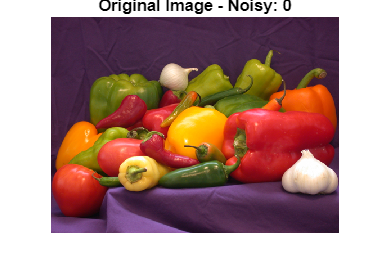

imagePath = 'peppers.png'; % Replace 'your_image_path.jpg' with the actual path to your image
threshold = 2300; % You may need to adjust this threshold based on your specific images

isNoisy = classifyNoisyImage(imagePath, threshold);

function isNoisy = classifyNoisyImage(imagePath, threshold)
    % Read the input image
    inputImage = imread(imagePath);
    
    % Convert the image to grayscale
    grayscaleImage = rgb2gray(inputImage);
    
    % Compute the variance of pixel intensities
    imageVariance = var(double(grayscaleImage(:)));
    
    % Compare the variance with the threshold to classify as noisy or not
    isNoisy = imageVariance > threshold;
    
    % Display the original image
    figure;
    imshow(inputImage);
    title(['Original Image - Noisy: ', num2str(isNoisy)]);
end